## Plot raw data recorded with gyroscope to find its offset

The arduino sketch prints 

- the time in milliseconds, 

- the angle phi in degrees,

- the angular velocity omega in degrees per second,

- the signal returned by the sensor (before conversion to degrees per second, before offset compensation). 

The next code block reads this data, extracts t and phi, and plots phi as a function of t. 

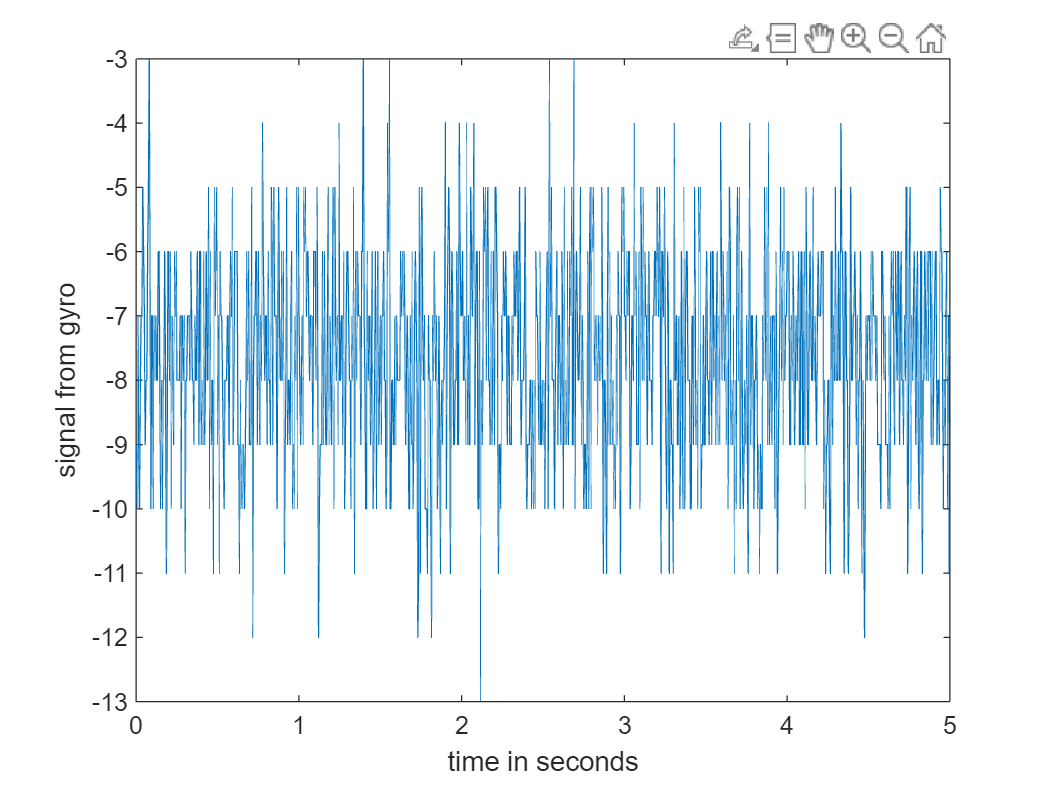

close all; 
clear all;
filename_step_response_data= "../arduino/record_gyroscope_data_for_matlab/calibration_data_for_matlab.txt";
step_response_data= readtable(filename_step_response_data);

tdata= step_response_data{:, 1}; 
tdata= tdata- tdata(1); % subtract t0
tdata= tdata/1e6; % turn microseconds into seconds
gyro_y_raw= step_response_data{:, 4};

plot(tdata, gyro_y_raw);
ylabel("signal from gyro"); 
xlabel("time in seconds"); 

We can calculate the mean and use it to compensate the signal offset.

gyro_y_raw_offset= sum(gyro_y_raw(:))/length(gyro_y_raw)

gyro_y_raw_offset = -7.6220